Fs = 48000; 
nBits = 16;
nChannels = 1;

rec1 = audiorecorder(Fs, nBits, nChannels, 1); 
rec2 = audiorecorder(Fs, nBits, nChannels, 2); 

disp("Start Recording")

Recording from 4 devices...


record(rec1); 
record(rec2); 
pause(5); 
stop(rec1);
stop(rec2);
disp("End of recording.")

End of recording.



mic1 = getaudiodata(rec1);
mic2 = getaudiodata(rec2);

Data saved to test.csv


% data = readmatrix('mic_data_40cm.csv');
% mic1 = data(:,1);
% mic2 = data(:,2);
% Fs = 40000; %Humans can hear up to about 20,000 Hz.
% nBits = 16;

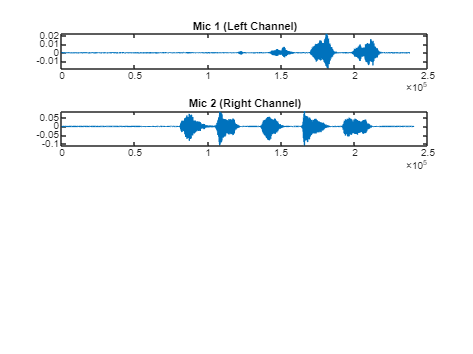

figure;
subplot(2,1,1); plot(mic1); title('Mic 1 (Left Channel)');
subplot(2,1,2); plot(mic2); title('Mic 2 (Right Channel)');

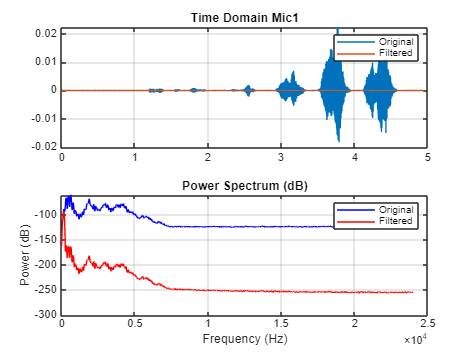

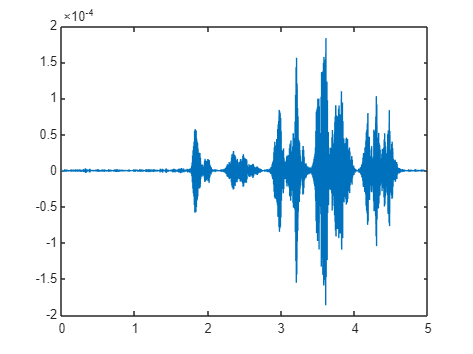

minLength = min(length(mic1), length(mic2));
mic1 = mic1(1:minLength);
mic2 = mic2(1:minLength);
t = (0:minLength-1) * (1/Fs);

% Lowpass
mic1_f = bandpass(mic1, [85 250], Fs);
mic2_f = bandpass(mic2, [85 250], Fs);

% Mic 1
figure; subplot(2,1,1);
plot(t, mic1); hold on; plot(t, mic1_f);
title('Time Domain Mic1'); legend('Original','Filtered');

subplot(2,1,2);
[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on; plot(ff1, 10*log10(pf1), 'r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');

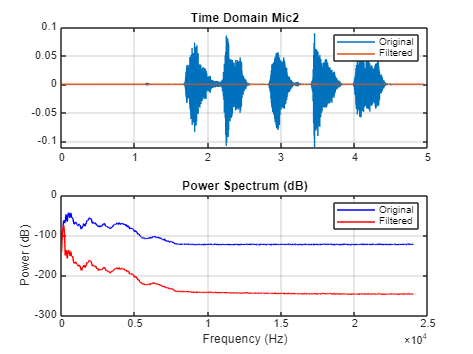


% Mic 2
figure; subplot(2,1,1);
plot(t, mic2); hold on; plot(t, mic2_f);
title('Time Domain Mic2'); legend('Original','Filtered');

subplot(2,1,2);
[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), '-b'); hold on; plot(ff2, 10*log10(pf2), '-r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
grid on;

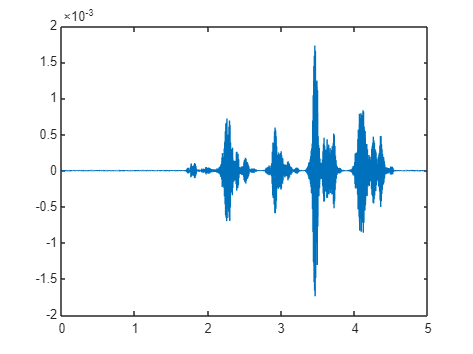


figure;

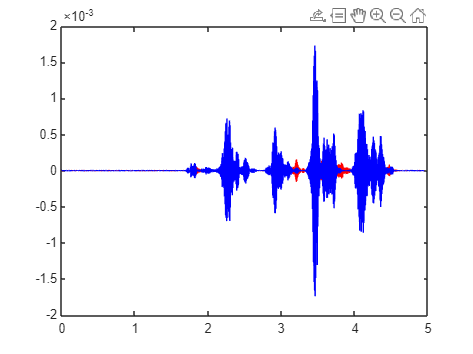

plot(t,mic1_f,"r")
hold on
plot(t,mic2_f,"b")
hold off

% TDOA
mic_spacing_m = 1; % Set your actual mic spacing in meters
v_sound = 343;     % m/s
max_delay_s = mic_spacing_m / v_sound;   % e.g. ~0.003 s
max_lag_samples = round(max_delay_s * Fs) ;  
% Normalized cross-correlation (GCC-style, time domain)
[xc12, lags12] = xcorr(mic1_f, mic2_f, max_lag_samples, 'normalized');
[~, idx12] = max(abs(xc12));
lag12       = lags12(idx12);
delay12     = lag12 / Fs;

fprintf('Lag:   %d samples\n', lag12);

Lag:   83 samples


fprintf('Delay: %.6f s  (%.4f ms)\n', delay12, delay12*1000);

Delay: 0.001729 s  (1.7292 ms)



v = 343; 
distance_mic = delay12 * v;

distance_diff = 0.5931

fprintf('Distance: %.3f\n',distance_mic);
L = 0.5;

L = 0.5000

angle12 = rad2deg(acos(distance_diff/0.5))

angle12 = 0.0000 +34.4443i

Ts = 1/Fs;
N = length(mic1);
t = (0:N-1)*Ts;

% Filter
mic1_f = bandpass(mic1, [85 250], Fs);
mic2_f = bandpass(mic2, [85 250], Fs);
mic3_f = bandpass(mic3, [85 250], Fs);
mic4_f = bandpass(mic4, [85 250], Fs);

% Mic 1
figure;
subplot(2,1,1);
plot(t, mic1); hold on;
plot(t, mic1_f);
title('Time Domain Mic1');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on;
plot(ff1, 10*log10(pf1), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

% Mic 2
figure;
subplot(2,1,1);
plot(t, mic2); hold on;
plot(t, mic2_f);
title('Time Domain Mic2');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), 'b'); hold on;
plot(ff2, 10*log10(pf2), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

% Mic 3
figure;
subplot(2,1,1);
plot(t, mic3); hold on;
plot(t, mic3_f);
title('Time Domain Mic3');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po3,fo3] = pspectrum(mic3, Fs);
[pf3,ff3] = pspectrum(mic3_f, Fs);

plot(fo3, 10*log10(po3), 'b'); hold on;
plot(ff3, 10*log10(pf3), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

% Mic 4
figure;
subplot(2,1,1);
plot(t, mic4); hold on;
plot(t, mic4_f);
title('Time Domain Mic4');
legend('Original','Filtered');
grid on;

subplot(2,1,2);

[po4,fo4] = pspectrum(mic4, Fs);
[pf4,ff4] = pspectrum(mic4_f, Fs);

plot(fo4, 10*log10(po4), 'b'); hold on;
plot(ff4, 10*log10(pf4), 'r');

title('Power Spectrum (dB)');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Original','Filtered');
grid on;

% Voice Activity Detection
% 
% ambient = readmatrix('ambient.csv');
% amb1 = ambient(:,1);
% amb2 = ambient(:,2);
% amb3 = ambient(:,3);
% amb4 = ambient(:,4);
% 
% amb1_f = bandpass(amb1, [85 250], Fs);
% amb2_f = bandpass(amb2, [85 250], Fs);
% amb3_f = bandpass(amb3, [85 250], Fs);
% amb4_f = bandpass(amb4, [85 250], Fs);
% 
window = 500;   % adjust based on Fs
% energy_amb = movmean(amb2_f.^2, window);

energy_mic = movmean(mic1_f.^2, window);
% Normalize the raw signal (absolute values) to a 0-1 scale
norm_mic = (mic1_f) / max((mic1_f));

% Normalize the energy to a 0-1 scale
norm_energy = energy_mic / max(energy_mic);
figure;
plot(norm_mic, 'Color', [0.7 0.7 0.7]); % Light gray for raw data
hold on;
plot(norm_energy, 'r', 'LineWidth', 2);  % Bold red for energy
title('Verification: Normalized Signal vs. Energy Envelope');
legend('Raw Signal ', 'Moving Mean Energy');
%% ── 1. Energy signal + threshold ────────────────────────────────────────
threshold = mean(energy_mic) * 1;
active_idx = energy_mic > threshold;

%% ── 2. Active mask + snap boundaries ────────────────────────────────────
edges  = diff([0; active_idx; 0]);
starts = find(edges == 1);
ends   = find(edges == -1) - 1;
num_snaps = length(starts);

figure;
plot(energy_mic, 'b-', 'LineWidth', 1); hold on;
yline(threshold, 'r--', 'LineWidth', 1.5, 'Label', 'Threshold');
yline(threshold, 'r--', 'LineWidth', 1.2);
for i = 1:num_snaps
    xregion(starts(i), ends(i), 'FaceColor', [1 0.8 0], 'FaceAlpha', 0.3);
end
xlabel('Frame Index');
ylabel('Energy');
title(sprintf('Detected Snaps (n = %d)', num_snaps));
grid on;


%% ── 3. Per-snap processing ───────────────────────────────────────────────
for i = 1:num_snaps
    s_idx = starts(i);
    e_idx = ends(i);
    fprintf('Snap %d: Index %d to %d\n', i, s_idx, e_idx);

    mic1_ac = mic1_f(s_idx:e_idx);
    mic2_ac = mic2_f(s_idx:e_idx);
    mic3_ac = mic3_f(s_idx:e_idx);
    mic4_ac = mic4_f(s_idx:e_idx);

    %% ── 3a. Raw waveforms for this snap ─────────────────────────────────
    t_snap = (0:length(mic1_ac)-1) / Fs;
    figure;

    subplot(2,1,1); 
    plot(t_snap, mic1_ac, 'b'); % Blue for Mic 1
    hold on;                    % Keep Mic 1 on the plot
    plot(t_snap, mic2_ac, 'r'); % Red for Mic 2
    hold off;                   % Reset for the next loop iteration
    title('Mic 1 (Blue) vs Mic 2 (Red)'); 
    xlabel('Time (s)'); ylabel('Amplitude'); grid on;


    subplot(2,1,2); 
    plot(t_snap, mic3_ac, 'k'); % Black for Mic 3
    hold on;                    % Keep Mic 3 on the plot
    plot(t_snap, mic4_ac, 'm'); % Magenta for Mic 4
    hold off;                   % Reset
    title('Mic 3 (Black) vs Mic 4 (Magenta)'); 
    xlabel('Time (s)'); ylabel('Amplitude'); grid on;
    sgtitle(sprintf('Snap %d — Raw Waveforms', i));

    %% ── 3b. Cross-correlation Mic 1 & 2 ─────────────────────────────────
    [xc12, lags12] = xcorr(mic1_ac, mic2_ac);
    [~, idx12]     = max(abs(xc12));
    lag12          = lags12(idx12);
    delay12        = lag12 / Fs;

    figure;
    plot(lags12/Fs, xc12, 'b-', 'LineWidth', 1.2); hold on;
    xline(delay12, 'r--', 'LineWidth', 1.5, ...
          'Label', sprintf('Peak: %.4f ms', delay12*1e3));
    xlabel('Time Lag (s)');
    ylabel('Correlation');
    title(sprintf('Snap %d — Cross-correlation: Mic 1 vs Mic 2', i));
    grid on;

    %% ── 3c. Cross-correlation Mic 3 & 4 ─────────────────────────────────
    [xc34, lags34] = xcorr(mic3_ac, mic4_ac);
    [~, idx34]     = max(abs(xc34));
    lag34          = lags34(idx34);
    delay34        = lag34 / Fs;

    figure;
    plot(lags34/Fs, xc34, 'r-', 'LineWidth', 1.2); hold on;
    xline(delay34, 'b--', 'LineWidth', 1.5, ...
          'Label', sprintf('Peak: %.4f ms', delay34*1e3));
    xlabel('Time Lag (s)');
    ylabel('Correlation');
    title(sprintf('Snap %d — Cross-correlation: Mic 3 vs Mic 4', i));
    grid on;
    %% ── 3d. Angle summary bar chart ─────────────────────────────────────
    c   = 343;
    d   = 0.3;
    val12 = (c * delay12) / d;
    val34 = (c * delay34) / d;

    % Clamp to [-1,1] to guard against numerical noise before acos
    phi1 = rad2deg(acos(max(-1, min(1, val12))));
    phi2 = rad2deg(acos(max(-1, min(1, val34))));

    figure;
    bar([phi1, phi2], 0.4, 'FaceColor', [0.2 0.5 0.8]);
    set(gca, 'XTickLabel', {'Mic 1-2 (\phi_1)', 'Mic 3-4 (\phi_2)'});
    ylabel('Angle (degrees)');
    ylim([0 180]);
    title(sprintf('Snap %d — Estimated Arrival Angles', i));
    text(1, phi1 + 4, sprintf('%.1f°', phi1), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    text(2, phi2 + 4, sprintf('%.1f°', phi2), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    grid on;

    fprintf('Delay Mic1-Mic2: %.6f s\n', delay12);
    fprintf('Delay Mic3-Mic4: %.6f s\n', delay34);
    fprintf('Phi1: %.2f deg  |  Phi2: %.2f deg\n\n', phi1, phi2);
end